clear;clc;

origState = rng(17);
msg = randi([0 1],800,1);
%Generate complex signals
cfg4a = lrwpanHRPConfig( ...
    Mode='802.15.4a', ...
    MeanPRF=15.6, ...
    Channel=3, ...
    CodeIndex=6, ...
    PSDULength=length(msg)/8) %#ok<NOPTS>

cfg4a =   lrwpanHRPConfig with properties:

             Channel: 3
                Mode: '802.15.4a'
             MeanPRF: 15.6000
            DataRate: 0.8500
     SamplesPerPulse: 4
           CodeIndex: 6
     PreambleMeanPRF: 16.1000
    PreambleDuration: 64
             Ranging: 0
          PSDULength: 100

   Read-only properties:
          SampleRate: 1.9968e+09


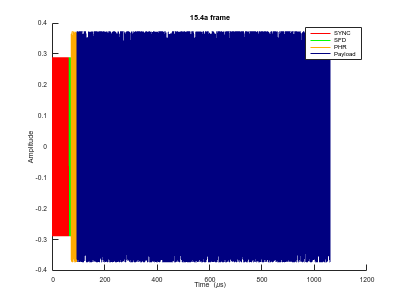

wave4a = lrwpanWaveformGenerator(msg,cfg4a);
%Note: It is a baseband signal.
lrwpanPlotFrame(wave4a,cfg4a);

%HPRF has configuration of samplesPerPulse

info(cfg4a ...
    )

ans = struct with fields:
                    PeakPRF: 499.2000
            BurstsPerSymbol: 32
               NumHopBursts: 8
              ChipsPerBurst: 16
             ChipsPerSymbol: 512
        ConvolutionalCoding: 1
         PreambleCodeLength: 31
    PreambleSpreadingFactor: 16



indices = lrwpanHRPFieldIndices(cfg4a); % length (start/end) of each field
preamble = wave4a( ...
    1:indices.SYNC(end)/cfg4a.PreambleDuration); % 1 of the Nsync repetitions
% plot(preamble)


%这是调制后的载波
channelSpec = [3 4992.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #3: Center frequency = 4992.8 MHz, Bandwidth = 499.2 MHz.


% 计算信号的频谱
N = length(wave4a); % 信号长度
Fs = cfg4a.SampleRate; % 采样频率
frequencies = Fs * (0:(N/2))/N; % 计算频率轴
signal_fft = fft(wave4a); % 使用 FFT 计算频谱
signal_fft_abs = abs(signal_fft/N); % 计算幅度谱密度

% 绘制频谱图
figure;
plot(frequencies, 2 * signal_fft_abs(1:N/2+1));
xlabel('频率 (Hz)');
ylabel('幅度');
title('UWB信号的频谱');


% Add the channel model
environmentType = "Outdoor";
LOS             = true;
d = 7; % distance between transmitter and receiver, in meters
sampleDensity   = 10000;
maxDopplerShift = 0; % in Hz
uwbChan = uwbChannel(environmentType, LOS, ChannelNumber=channelNum, Distance=d, ...
SampleRate=cfg4a.SampleRate, SampleDensity=sampleDensity, MaxDopplerShift=maxDopplerShift, ...
Visualization="Impulse response");

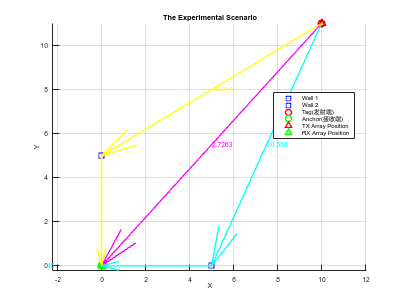

% wave4a=zeros(1,1)
% 定义墙面特性
wall1_position = [5, 0]; % 墙面1位置
wall2_position = [0, 5]; % 墙面2位置
reflection_coefficient = 0.8; % 反射系数

% 定义天线特性
tx_antenna_gain = 2; % 发射天线增益为 2 dB
rx_antenna_gain = 2; % 接收天线增益为 2 dB

% 计算传播路径
rx_position = [0, 0]; 
tx_position = [10,11]; 

% 绘制墙面和发射接收器位置
figure;
hold on;
plot(wall1_position(1), wall1_position(2), 'bs', 'MarkerSize', 10, 'LineWidth', 2); % 墙面1位置
plot(wall2_position(1), wall2_position(2), 'bs', 'MarkerSize', 10, 'LineWidth', 2); % 墙面2位置
plot(tx_position(1), tx_position(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2); % 发射器位置
plot(rx_position(1), rx_position(2), 'go', 'MarkerSize', 10, 'LineWidth', 2); % 接收器位置


% 添加天线阵列
tx_array_length = 3;
rx_array_length = 3;
c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/4992.8e6;
antennaSpacing = lambda / 2;
tx_array_spacing = antennaSpacing;
rx_array_spacing = antennaSpacing;
tx_array_angle = 135; % 发射端天线阵列与水平轴夹角
rx_array_angle = 135; % 接收端天线阵列与水平轴夹角

% 计算天线阵列位置
tx_array_positions = [tx_position-[tx_array_spacing,0];tx_position;tx_position+[tx_array_spacing,0]];
rx_array_positions = [rx_position-[rx_array_spacing,0];rx_position;rx_position+[rx_array_spacing,0]];


% 将天线阵列位置进行旋转
tx_array_positions = rotate_points(tx_array_positions, tx_array_angle, tx_position);
rx_array_positions = rotate_points(rx_array_positions, rx_array_angle, rx_position);

% 绘制天线阵列
plot(tx_array_positions(:, 1), tx_array_positions(:, 2), 'r^', 'MarkerSize', 8, 'LineWidth', 2);
plot(rx_array_positions(:, 1), rx_array_positions(:, 2), 'g^', 'MarkerSize', 8, 'LineWidth', 2);

xlabel('X');
ylabel('Y');
title('The Experimental Scenario');
legend('Wall 1', 'Wall 2', 'Tag(发射端)', 'Anchor(接收端)', 'TX Array Position', 'RX Array Position', 'Location', 'best');
grid on;
axis equal;

% 旋转函数
function rotated_points = rotate_points(points, angle, center)
    theta = deg2rad(angle);
    rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated_points = (rotation_matrix * (points' - center') + center')';
end

% 计算锚点到标签的向量
vecAnchorToTag = tx_position - rx_position;

% 计算标签到锚点的向量
vecTagToAnchor = rx_position - tx_position;

% 计算墙面1到标签的向量
vecWall1ToTag = wall1_position - tx_position;

% 计算墙面2到标签的向量
vecWall2ToTag = wall2_position - tx_position;

% 计算墙面1到锚板的向量
vecWall1ToAnchor = -wall1_position + rx_position;

% 计算墙面2到锚板的向量
vecWall2ToAnchor = -wall2_position + rx_position;

% 计算向量的长度
distAnchorToTag = norm(vecAnchorToTag);
disWall1ToTag = norm(vecWall1ToTag);
disWall2ToTag = norm(vecWall2ToTag);
disWall1ToAnchor = norm(vecWall1ToAnchor);
disWall2ToAnchor = norm(vecWall2ToAnchor);

% 计算Actual AOD（以弧度为单位）
angleTagToAnchor = acos(dot(vecTagToAnchor, [-1/sqrt(2), -1/sqrt(2)]) / distAnchorToTag);
angleWall1ToTag = acos(dot(vecWall1ToTag, [-1/sqrt(2), -1/sqrt(2)]) / disWall1ToTag);
angleWall2ToTag = acos(dot(vecWall2ToTag, [-1/sqrt(2), -1/sqrt(2)]) / disWall2ToTag);
% 将夹角转换为度数
angleTagToAnchor = rad2deg(angleTagToAnchor);
angleWall1ToTag = rad2deg(angleWall1ToTag);
angleWall2ToTag = rad2deg(angleWall2ToTag);

% 计算Actual AOA（以弧度为单位）
angleAnchorToTag = acos(dot(vecTagToAnchor, [-1/sqrt(2), -1/sqrt(2)]) / distAnchorToTag);
angleWall1ToAnchor = acos(dot(vecWall1ToAnchor, [-1/sqrt(2), -1/sqrt(2)]) / disWall1ToAnchor);
angleWall2ToAnchor = acos(dot(vecWall2ToAnchor, [-1/sqrt(2), -1/sqrt(2)]) / disWall2ToAnchor);
% 将夹角转换为度数
angleAnchorToTag = rad2deg(angleAnchorToTag);
angleWall1ToAnchor  = rad2deg(angleWall1ToAnchor );
angleWall2ToAnchor = rad2deg(angleWall2ToAnchor);


% 绘制天线阵列
plot(tx_array_positions(:, 1), tx_array_positions(:, 2), 'r^', 'MarkerSize', 8, 'LineWidth', 2);
plot(rx_array_positions(:, 1), rx_array_positions(:, 2), 'g^', 'MarkerSize', 8, 'LineWidth', 2);


% 绘制向量及角度
quiver(tx_position(1), tx_position(2), vecTagToAnchor(1), vecTagToAnchor(2), 0, 'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', 'm');
text(tx_position(1) + vecTagToAnchor(1)/2, tx_position(2) + vecTagToAnchor(2)/2, num2str(angleTagToAnchor), 'Color', 'm');
quiver(tx_position(1), tx_position(2), vecWall1ToTag(1), vecWall1ToTag(2), 0, 'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', 'c');
text(tx_position(1) + vecWall1ToTag(1)/2, tx_position(2) + vecWall1ToTag(2)/2, num2str(angleWall1ToTag), 'Color', 'c');
quiver(tx_position(1), tx_position(2), vecWall2ToTag(1), vecWall2ToTag(2), 0, 'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', 'y');
text(tx_position(1) + vecWall2ToTag(1)/2, tx_position(2) + vecWall2ToTag(2)/2, num2str(angleWall2ToTag), 'Color', 'y');

quiver(wall1_position(1), wall1_position(2), vecWall1ToAnchor(1), vecWall1ToAnchor(2), 0, 'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', 'c');
text(rx_position(1) + vecWall1ToAnchor(1)/2, rx_position(2) + vecWall1ToAnchor(2)/2, num2str(angleWall1ToAnchor), 'Color', 'c');
quiver(wall2_position(1), wall2_position(2), vecWall2ToAnchor(1), vecWall2ToAnchor(2), 0, 'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', 'y');
text(rx_position(1) + vecWall2ToAnchor(1)/2, rx_position(2) + vecWall2ToAnchor(2)/2, num2str(angleWall2ToAnchor), 'Color', 'y');
xlabel('X');
ylabel('Y');
title('The Experimental Scenario');
legend('Wall 1', 'Wall 2', 'Tag(发射端)', 'Anchor(接收端)', 'TX Array Position', 'RX Array Position', 'Location', 'best');
grid on;
axis equal;



% 计算参考向量的叉乘以确定角度的正负值
cross_product = cross([-1/sqrt(2), -1/sqrt(2), 0], [vecAnchorToTag, 0]);

% 如果参考向量在向量[-1/sqrt(2), -1/sqrt(2)]的上方，则夹角为负值，否则为正值
if cross_product(3) > 0
    angleAnchorToTag = -angleAnchorToTag;
end

% xlabel('X');
% ylabel('Y');
% title('The Experimental Scenario');
% legend('Wall 1', 'Wall 2', 'Tag(发射端)', 'Anchor(接收端)', 'TX Array Position', 'RX Array Position', 'Location', 'best');
% grid on;
% axis equal;

function adjusted_array = adjust_to_range(array)
    adjusted_array = array;
    for i = 1:numel(array)
        while adjusted_array(i) > pi
            adjusted_array(i) = adjusted_array(i) - 2*pi;
        end
        while adjusted_array(i) < -pi
            adjusted_array(i) = adjusted_array(i) + 2*pi;
        end
    end
end

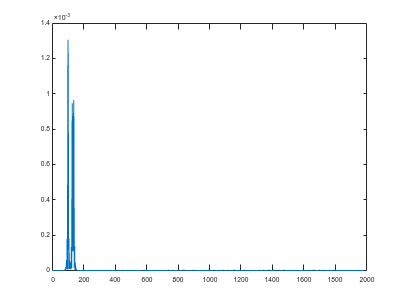

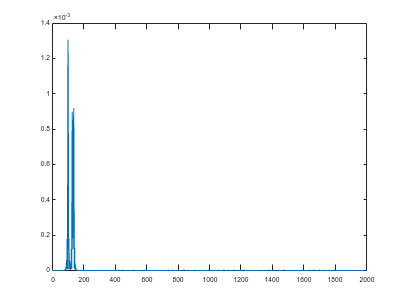

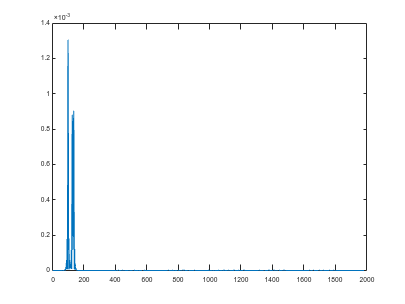

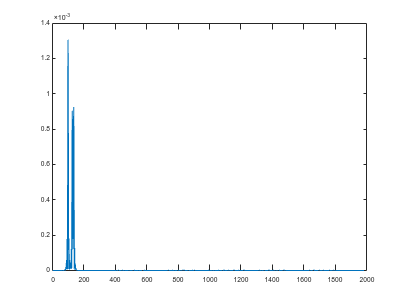

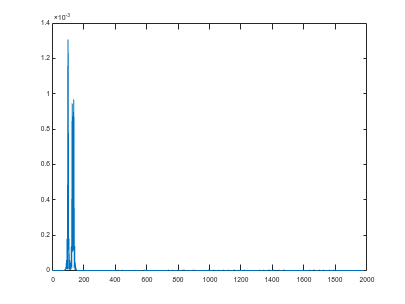

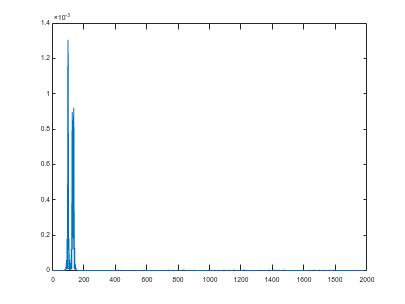

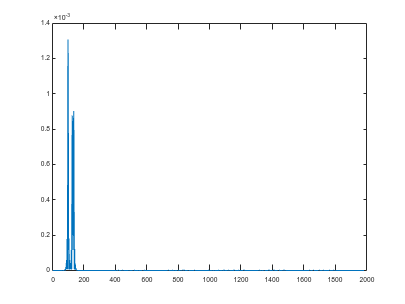

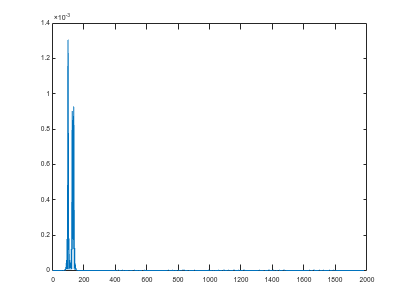

% peaksPhase=cell(rx_array_length*tx_array_length,1);
% timestamp=cell(rx_array_length*tx_array_length,1);
peaksPhase=[];
timestamp=[];
cir_data=[];
frequency=4992.8e6;
fs=cfg4a.SampleRate;
peaksInterval=12;
for j=1:3
    rx_position = rx_array_positions(j,:);
    for i=1:tx_array_length
        tx_position = tx_array_positions(i,:);
        direct_path_distance = norm(rx_position - tx_position); % 直射路径距离
        reflection1_distance = norm(wall1_position - tx_position) + norm(wall1_position - rx_position); % 墙面1反射路径距离
        reflection2_distance = norm(wall2_position - tx_position) + norm(wall2_position - rx_position); % 墙面2反射路径距离

        % % 接收信号与发射信号的幅度比
        received_signal_direct=wave4a * lambda / (4*pi*direct_path_distance);
        received_signal_reflection1=wave4a * reflection_coefficient * lambda / (4*pi*reflection1_distance);
        received_signal_reflection2=wave4a * reflection_coefficient * lambda / (4*pi*reflection2_distance);

        % % % 接收信号与发射信号的幅度比
        % received_signal_direct=wave4a;
        % received_signal_reflection1=wave4a;
        % received_signal_reflection2=wave4a;
        

        % % % 设置更高的采样频率
        % fs = 5 * cfg4a.SampleRate; 
        % % % 得到各个path的多经时延信号，并进行upsampling
        % received_signal_direct = resample(received_signal_direct, fs, cfg4a.SampleRate);
        % received_signal_reflection1 = resample(received_signal_reflection1, fs, cfg4a.SampleRate);
        % received_signal_reflection2 = resample(received_signal_reflection2, fs, cfg4a.SampleRate);
        % % preamble=resample(preamble,fs,cfg4a.SampleRate);

        % 定义传播速度（假设与光速相同）
        speed_of_light = physconst("Lightspeed");

        % 计算传播时延
        direct_path_delay = direct_path_distance / speed_of_light; % 直射路径时延（秒）
        reflection1_delay = reflection1_distance / speed_of_light;% 反射路径1时延（秒）
        reflection2_delay = reflection2_distance / speed_of_light; % 反射路径2时延（秒）



        %得到各个path的多经时延信号
        received_signal_direct_delayed = [zeros(round(direct_path_delay * fs),1) ;received_signal_direct];
        received_signal_reflection1_delayed = [zeros(round(reflection1_delay * fs)+peaksInterval,1) ;received_signal_reflection1];
        received_signal_reflection2_delayed = [zeros(round(reflection2_delay * fs)+2*peaksInterval,1); received_signal_reflection2];

        len1 = length(received_signal_direct_delayed);
        len2 = length(received_signal_reflection1_delayed);
        len3 = length(received_signal_reflection2_delayed);
        maxLen = max(len1,len2);
        maxLen =max(maxLen,len3);
        received_signal_direct_delayed = [received_signal_direct_delayed; zeros(maxLen - len1,1)];
        received_signal_reflection1_delayed = [received_signal_reflection1_delayed; zeros(maxLen - len2,1)];
        received_signal_reflection2_delayed=[received_signal_reflection2_delayed; zeros(maxLen - len3,1)];

    
        % Calculate the phase shift for each path
        direct_path_phase_shift = exp(-1j * 2 * pi * direct_path_distance / lambda);
        reflection1_phase_shift = exp(-1j * 2 * pi * reflection1_distance / lambda);
        reflection2_phase_shift = exp(-1j * 2 * pi * reflection2_distance / lambda);

        % Apply phase shifts to received signals
        received_signal_direct_phase = received_signal_direct_delayed .* direct_path_phase_shift;
        received_signal_reflection1_phase = received_signal_reflection1_delayed .* reflection1_phase_shift;
        received_signal_reflection2_phase = received_signal_reflection2_delayed .* reflection2_phase_shift;

    
        % 组合多径时延后的信号
        received_signal_total = received_signal_direct_phase + ...
            received_signal_reflection1_phase + received_signal_reflection2_phase;
          % received_signal_total = received_signal_direct_delayed + ...
          %   received_signal_reflection1_delayed + received_signal_reflection2_delayed;
        
        % 
        % 添加噪声
        noise_power = -80; % 噪声功率为 -80 dBm
        noise = awgn(zeros(size(received_signal_total)), noise_power, 'measured'); % 生成高斯白噪声
        
        %最终信号
        received_signal = received_signal_total + noise;
        % received_signal = received_signal_reflection1_delayed +received_signal_reflection2_delayed+ noise;
        receivedCorrelation=CalculateXCorr(preamble,received_signal);
        reshaped_correlation = reshape(receivedCorrelation(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
        average_correlation = mean(reshaped_correlation, 2);
        abs_correlation=abs(average_correlation);
        % 对每列求平均
        figure;
        plot(abs_correlation);
        % numSamples = length(average_correlation); % 样本数
        % t = (0:numSamples-1)*1e9 / fs;
        % figure;
        % plot(t,average_correlation/max(average_correlation));
        % xlabel('ns');
        % ylabel('amplitude');
        cir_data=[cir_data;receivedCorrelation(1:length(preamble))'];
        [peaksChosen,peaksChosenValue]=findMPC(abs_correlation);
        phases=receivedCorrelation(peaksChosen);
        peaksPhase=[peaksPhase;phases(1:end)'];
        timestamp=[timestamp;[peaksChosen(1),peaksChosen(2)-peaksInterval,peaksChosen(3)-2*peaksInterval]*1e9 / fs];
    end
end

%peaksPhase为NTX发射，某一接收天线收到的NTX个相位
function AOD=CalculateAOD(peaksPhase,tx_array_length,rx_array_length,antennaSpacing,frequency)
    % 初始化一个 cell 数组用于存储分割后的子矩阵
    rx_matrices = cell(1, rx_array_length);
    % 使用循环分割矩阵
    for i = 1:tx_array_length
        start_row = (i - 1) * rx_array_length + 1;
        end_row = i * rx_array_length;
        % 提取当前子矩阵并存储到 cell 数组中
        rx_matrices{i} = peaksPhase(start_row:end_row, :);
    end
    AOD=[];
    for i = 1:rx_array_length
        peaksPhases=angle(rx_matrices{i});
        phaseDifferences=diff(peaksPhases);
        phaseDifferences=adjust_to_range(phaseDifferences);
        phaseSum=sum(phaseDifferences,1);
        % 计算相位差对应的到达角度（以弧度为单位）
        c=physconst('Lightspeed');
        theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
        theta_radians2 = asin(phaseSum* c / (2 * pi * 2 * antennaSpacing * frequency));
        % 将弧度转换为度数
        theta_degrees = rad2deg(theta_radians);
        theta_degrees2 = rad2deg(theta_radians2);
        theta_degrees=[theta_degrees;theta_degrees2];
        AOD=[AOD;mean(theta_degrees)];
    end
end


%peaksPhase为某个TX发射，NRX个接收天线接收的相位
function AOA=CalculateAOA(peaksPhase,tx_array_length,rx_array_length,antennaSpacing,frequency)
    % 初始化一个 cell 数组用于存储分割后的子矩阵
    tx_matrices = cell(1, tx_array_length);
    % 使用循环分割矩阵
    for i = 1:tx_array_length
        % 提取当前子矩阵并存储到 cell 数组中
        tx_matrices{i} = peaksPhase(i:tx_array_length:length(peaksPhase),:);
    end
    AOA=[];
    for i=1:tx_array_length            
            peaksPhases=angle(tx_matrices{i});
            phaseDifferences=diff(peaksPhases);
            phaseDifferences=adjust_to_range(phaseDifferences);
            phaseSum=sum(phaseDifferences,1);
            % 计算相位差对应的到达角度（以弧度为单位）
            c=physconst('Lightspeed');
            theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
            theta_radians2 = asin(phaseSum* c / (2 * pi * 2 * antennaSpacing * frequency));
            % 将弧度转换为度数
            theta_degrees = rad2deg(theta_radians);
            theta_degrees2 = rad2deg(theta_radians2);
            theta_degrees=[theta_degrees;theta_degrees2];
            AOA=[AOA;mean(theta_degrees)];
    end
end

matched_peaks=matchCIRPeaks(cir_data,0.3,0.5,1.0);
for i = 1:tx_array_length*rx_array_length
    cir=cir_data(i,:);
    fprintf('CIR %d:\n', i);
    disp('Matched Peaks:');
    disp(matched_peaks{i}.peaks);
    disp('Matched Locations:');
    disp(matched_peaks{i}.locs);
    peakChosen=matched_peaks{i}.locs;
    peaksPhase=[peaksPhase;cir(peakChosen)];
    timestamp=[timestamp;matched_peaks{i}.locs*1e9 / fs];
end

AOD=CalculateAOD(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency)

AOD =    -2.8379  -20.8279   14.2769
   -2.7297  -19.8141   13.3614
   -2.6097  -20.7021   14.1672


AOD=mean(AOD)

AOD =    -2.7258  -20.4480   13.9352


AOA=CalculateAOA(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency)

AOA =     2.6106  -44.7949   44.8095
    2.7234  -45.9797   45.9386
    2.8387  -44.6324   44.6551


AOA=mean(AOA)

AOA =     2.7243  -45.1356   45.1344


timestamp=timestamp

timestamp =    49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889
   49.5793   57.0913   55.5889


timestamp=mean(timestamp,1);
rTOF=timestamp-timestamp(1);
rDistance=rTOF*physconst('Lightspeed')*1e-9;

actualAOD=[angleAnchorToTag,angleWall1ToTag,angleWall2ToTag];
actualAOA=[angleTagToAnchor,angleWall1ToAnchor,angleWall2ToAnchor];
display('Actual AOD:');

Actual AOD:


display(actualAOD);

actualAOD =     2.7263   20.5560   14.0362


display('Estimated AOD');

Estimated AOD


display(AOD);

AOD =    -2.7258  -20.4480   13.9352


display('Actual AOA:');

Actual AOA:


display(actualAOA);

actualAOA =     2.7263   45.0000   45.0000


display('Estimated AOA');

Estimated AOA


display(AOA);

AOA =     2.7243  -45.1356   45.1344


display('Actual rDistance:');

Actual rDistance:


display(sort([direct_path_distance,reflection1_distance,reflection2_distance]-direct_path_distance));

         0    1.7674    2.2488



display('Estimated rDistance');

Estimated rDistance


display(rDistance);

rDistance =          0    2.2520    1.8016


1/cfg4a.SampleRate*physconst('Lightspeed')

function x0 = findLocalization(theta1, theta2, phi1, phi2, rTOF)
    theta1 = deg2rad(theta1);
    theta2 = deg2rad(theta2);
    phi1 = deg2rad(phi1);
    phi2 = deg2rad(phi2);

    % 定义网格大小和范围
    gridRange = 20;
    gridSize = 0.5;

    % 生成网格点坐标
    [x1, y1, x2, y2] = ndgrid(-gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange);
    x0 = [x1(:), y1(:), x2(:), y2(:)];

    % 计算目标函数值
    objectiveValues = objectiveFunction(x0, theta1, theta2, phi1, phi2, rTOF);

    % 找到最小值
    [~, idx] = min(objectiveValues);
    x0 = x0(idx, :);
end

function fval = objectiveFunction(x, theta1, theta2, phi1, phi2, rTOF)
    x1 = x(:, 1);
    y1 = x(:, 2);
    x2 = x(:, 3);
    y2 = x(:, 4);

    % 计算目标函数值
    fval = (tan(theta1) - x1./y1).^2 + (tan(theta2) - x2./y2).^2 + (tan(phi1 + theta1 - phi2) - (x1 - x2)./(y1 - y2)).^2 +((rTOF * physconst('Lightspeed') * 1e-9) - (-sqrt(x1.^2 + y1.^2) + sqrt(x2.^2 + y2.^2) + sqrt((x1 - x2).^2 + (y1 - y2).^2))).^2;
end


function xOpt = optimizeLocalization(x0,theta1, theta2, phi1, phi2, rTOF)
    % 转换角度为弧度
    theta1 = deg2rad(theta1);
    theta2 = deg2rad(theta2);
    phi1 = deg2rad(phi1);
    phi2 = deg2rad(phi2);


    % 以找到的位置为中心，定义更精细的网格范围和步长
    fineRange = 1; % 细化范围为2个单位
    fineStep = 0.03; % 细化步长为0.1

    % -1:0.03:1
    % 生成更精细的网格点坐标
    [x1, y1, x2, y2] = ndgrid(x0(1)-fineRange:fineStep:x0(1)+fineRange, ...
                              x0(2)-fineRange:fineStep:x0(2)+fineRange, ...
                              x0(3)-fineRange:fineStep:x0(3)+fineRange, ...
                              x0(4)-fineRange:fineStep:x0(4)+fineRange);
    fineGrid = [x1(:), y1(:), x2(:), y2(:)];

    % 计算目标函数值
    fineObjectiveValues = objectiveFunction(fineGrid, theta1, theta2, phi1, phi2, rTOF);

    % 找到最小值
    [~, fineIdx] = min(fineObjectiveValues);
    xOpt = fineGrid(fineIdx, :);
end


tic;
x0=findLocalization(AOA(1),AOA(3),AOD(1),AOD(3),rTOF(3))

x0 =    -0.5000  -15.5000   -3.5000   -3.5000


x0=optimizeLocalization(x0,AOA(1),AOA(3),AOD(1),AOD(3),rTOF(3))

x0 =    -0.7200  -14.8800   -3.5400   -3.5100



% 顺时针旋转45°的旋转矩阵
x0=reshape(x0,2,2);
x0(2,:)=-x0(2,:)

x0 =    -0.7200   -3.5400
   14.8800    3.5100


theta = deg2rad(45);
R = [cos(theta), sin(theta); -sin(theta), cos(theta)];

% 旋转后的向量
rotated_vector = R * x0;

% 显示结果
disp(rotated_vector);

   10.0126   -0.0212
   11.0309    4.9851



toc;

Elapsed time is 1.452002 seconds.


result=solveOptimizationProblem(rotated_vector,AOA(1),AOA(3),AOD(1),AOD(3),rTOF(3))

Index in position 2 exceeds array bounds. Index must not exceed 2.

Error in new CIR>objectiveFunction (line 430)
    x2 = x(:, 3);

Error in new CIR>@(x)objectiveFunction(x,theta1,theta2,phi1,phi2,rTOF) (line 557)
   


x1=findLocalization(AOA(1),AOA(2),AOD(1),AOD(2),rTOF(2))

x1 =    -1.0000  -15.5000    3.5000   -3.5000


% 顺时针旋转45°的旋转矩阵
x1=reshape(x1,2,2);
x1(2,:)=-x1(2,:)

x1 =    -1.0000    3.5000
   15.5000    3.5000


theta = deg2rad(45);
R = [cos(theta), sin(theta); -sin(theta), cos(theta)];

% 旋转后的向量
rotated_vector1 = R * x1;
% 显示结果
disp(rotated_vector1);

   10.2530    4.9497
   11.6673    0.0000



display('Actual Localization:');

Actual Localization:


display(round(tx_position));

    10    11



display('Estimated Localization');

Estimated Localization


display(rotated_vector1(:,1));

   10.2530
   11.6673



result=(rotated_vector(:,1)+rotated_vector1(:,1))/2

result =    10.4298
   11.4905


%%Calculate the orientation of the antenna array 
orientation=atan(result(2)/result(1));
orientation=-AOA(1)+rad2deg(orientation)

orientation = 45.0460

function [a, b, c] = solve_triangle(alpha, beta, distance_diff)
    % 输入已知参数：两个角和距离差
    % alpha: 第一个角（弧度）
    % beta: 第二个角（弧度）
    % distance_diff: 两边之和与第三边的距离差
    
    % 检查输入角度是否合理
    if alpha + beta >= pi
        error('两个角的和必须小于180度');
    end

    % 设已知角度
    gamma = pi - alpha - beta; % 第三个角
    
    % 定义符号变量
    syms a b c
    
    % 利用余弦定理和距离差建立方程
    eqns = [...
        a + b - c == distance_diff, ...          % 距离差
        a^2 == b^2 + c^2 - 2*b*c*cos(alpha), ... % 余弦定理
        b^2 == a^2 + c^2 - 2*a*c*cos(beta), ...  % 余弦定理
        a > 0, b > 0, c > 0];                   % 限定条件: a, b, c 均大于0
    
    % 求解方程组
    solutions = solve(eqns, [a, b, c], 'Real', true);
    
    % 提取解
    a_sol = double(solutions.a);
    b_sol = double(solutions.b);
    c_sol = double(solutions.c);
    
    % 输出结果
    fprintf('三角形三边的边长分别为:\n');
    a = a_sol;
    b = b_sol;
    c = c_sol;
    % 输出结果
    fprintf('a = %.2f\n', a);
    fprintf('b = %.2f\n', b);
    fprintf('c = %.2f\n', c);
end

% 调用函数并输出结果
alpha = deg2rad(abs(AOA(1)-AOA(3))); % 例如30度
beta = deg2rad(abs(AOD(1)-AOD(3)));  % 例如45度
distance_diff = rDistance(3);   % 例如距离差为1

[a, b, c] = solve_triangle(alpha, beta, distance_diff);


% 计算顶点坐标
A = [0, 0]; % 顶点A位于原点
B = [0, c]; % 顶点B位于y轴正半轴上的点

% 计算顶点C的坐标
Cx = b * sin(beta);
Cy = c - b * sin(beta);
C = [Cx, Cy];


fprintf('顶点A的坐标为: (%.2f, %.2f)\n', A(1), A(2));
fprintf('顶点B的坐标为: (%.2f, %.2f)\n', B(1), B(2));
fprintf('顶点C的坐标为: (%.2f, %.2f)\n', C(1), C(2));


function [c, ceq] = nonlinearConstraints(x, rTOF)
    x1 = x(1);
    y1 = x(2);
    x2 = x(3);
    y2 = x(4);

    % 计算非线性等式约束条件
    a = norm([x1, y1]);
    b = norm([x2, y2]);
    c = norm([x1 - x2, y1 - y2]);
    ceq = b + c - a - rTOF * physconst('Lightspeed')*1e-9;

    % 非线性不等式约束为空
    c = [];
end


function result = solveOptimizationProblem(x0,theta1, theta2, phi1, phi2, rTOF)
    % 初始猜测值
   
    % 定义目标函数
    fun = @(x) objectiveFunction(x, theta1, theta2, phi1, phi2, rTOF);

    % 定义线性等式约束
    Aeq = [1, -tan(theta1), 0, 0; 0, 0, 1, -tan(theta2); 1, -1, -tan(theta1 + phi1 - phi2), tan(theta1 + phi1 - phi2)];
    beq = [0; 0; 0];

    % 定义非线性等式约束
    nonlcon = @(x) nonlinearConstraints(x, rTOF);

    % 定义变量下界和上界
    lb = [-30, -30, -30, -30];
    ub = [30, 30, 30, 30];

    % 执行优化
    result = fmincon(fun, x0, [], [], Aeq, beq, lb, ub, nonlcon);
end

% 顺时针旋转45°的旋转矩阵
result=reshape(result,2,2)
theta = deg2rad(45);
R = [cos(theta), -sin(theta); sin(theta), cos(theta)];

% 旋转后的向量
rotated_vector = R * result;

% 显示结果
disp(rotated_vector);

disp('Actual AOD:');
disp(angleAnchorToTag);
disp("Estimated AOD：");
disp(mean(theta_degrees,1));
disp("Mean Error:")
disp(mean(theta_degrees-angleAnchorToTag,1));

function PLd = distanceDependentPathLoss(d, d0, PL0, n, S)
    % 计算距离相关路径损耗
    PLd = PL0 + 10 * n * log10(d / d0) + S; % 使用给定的公式计算路径损耗
end

function PLf = frequencyDependentPathLoss(f, fc, kappa)
    % 计算频率相关路径损耗
    PLf = (f / fc)^(2 * kappa + 1); % 使用给定公式计算路径损耗
end

TOF1=direct_path_distance/physconst("Lightspeed")*1e9
TOF2=reflection1_distance/physconst("Lightspeed")*1e9
TOF3=reflection2_distance/physconst("Lightspeed")*1e9


function [peaksChosen,peaksChosenValue]=findMPC(cir)
    [peaksValue,peaksIdx]=findpeaks(cir);
    %设置阈值
    threshold=0.4*max(abs(cir));
    %找到所有在阈值之上的峰，需要记录峰的索引和峰值
    peaksChosen=peaksIdx(peaksValue>threshold);
    peaksChosenValue=peaksValue(peaksValue>threshold);
end

receivedCorrelation=CalculateXCorr(preamble,received_signal);
abs_correlation=abs(receivedCorrelation);
figure;
plot(abs_correlation(1984*0+1:1984*1));
reshaped_correlation = reshape(abs_correlation(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
% 对每列求平均
average_correlation = mean(reshaped_correlation, 2);
figure;
plot(average_correlation);
% % 计算持续时间
Fs = cfg4a.SampleRate; % 采样率
numSamples = length(average_correlation); % 样本数
% 
t = (0:numSamples-1)*1e9 / Fs;
figure;
plot(t,average_correlation);
xlabel('ns');
ylabel('amplitude')

[peaksChosen,peaksChosenValue]=findMPC(average_correlation)
peaksPhase=receivedCorrelation(peaksChosen)

c=physconst('Lightspeed');
tof=d/c;
samplesToDelay = tof * cfg4a.SampleRate;
vfd = dsp.VariableFractionalDelay;
reset(vfd);
release(vfd);
vfd.MaximumDelay = ceil(1.1*samplesToDelay);
delayedBlink = vfd( ...
    [wave4a; zeros(ceil(samplesToDelay), 1)], ...
    samplesToDelay);

function matched_peaks = matchCIRPeaks(cir_data, threshold, intensity_weight, position_weight)
    % cir_data: 数组，每个元素包含CIR数据
    % threshold: 检测峰值的阈值
    % peak_distance_tolerance: 峰位置匹配的容忍度
    % intensity_weight: 峰值强度权重
    % position_weight: 峰位置权重

    num_cir = size(cir_data,1);
    peaks_info = cell(num_cir, 1);
    % Step 1: 通过findpeaks找到每组CIR的峰值
    for i = 1:num_cir
        thre=threshold*max(abs(cir_data(i,:)));
        [peaks_first, locs_first] = findpeaks(abs(cir_data(i,:)));
      % 检查峰值数组和阈值比较
        valid_idx = peaks_first > thre;
        peaks = peaks_first(valid_idx);
        locs = locs_first(valid_idx);
        peaks_info{i}.peaks = peaks;
        peaks_info{i}.locs = locs;
    end
    
    % Step 2: 选择参考CIR
    peak_counts = cellfun(@(x) length(x.peaks), peaks_info);
    min_peak_count = min(peak_counts);
    
    % 找到所有峰值数量等于最小峰值数量的CIR
    candidate_indices = find(peak_counts == min_peak_count);
    
    if length(candidate_indices) > 1
        % 如果有多个候选者，则进一步使用标准差和峰值总和选择
        std_devs = cellfun(@(x) std(x.peaks), peaks_info(candidate_indices));
        total_intensities = cellfun(@(x) sum(x.peaks), peaks_info(candidate_indices));
        
        % 标准化
        std_devs = (std_devs - min(std_devs)) / (max(std_devs) - min(std_devs));
        total_intensities = (total_intensities - min(total_intensities)) / (max(total_intensities) - min(total_intensities));
        
        % 计算综合评分
        scores = std_devs + total_intensities;
        [~, min_score_idx] = min(scores);
        ref_idx = candidate_indices(min_score_idx);
    else
        ref_idx = candidate_indices(1);
    end
    
    ref_peaks = peaks_info{ref_idx}.peaks;
    ref_locs = peaks_info{ref_idx}.locs;
    
    matched_peaks = cell(num_cir, 1);
    
    % Step 3: 匹配峰值
    for i = 1:num_cir
        if i == ref_idx
            matched_peaks{i}.peaks = ref_peaks;
            matched_peaks{i}.locs = ref_locs;
            continue;
        end
        
        curr_peaks = peaks_info{i}.peaks;
        curr_locs = peaks_info{i}.locs;
        num_ref_peaks = length(ref_peaks);
        num_curr_peaks = length(curr_peaks);
        
        % Cost matrix for matching
        cost_matrix = zeros(num_ref_peaks, num_curr_peaks);
        for j = 1:num_ref_peaks
            for k = 1:num_curr_peaks
                intensity_diff = abs(ref_peaks(j) - curr_peaks(k));
                position_diff = abs(ref_locs(j) - curr_locs(k));
                cost_matrix(j, k) = intensity_weight * intensity_diff + position_weight * position_diff;
            end
        end
        
        % Hungarian algorithm for optimal matching
        display(cost_matrix);
        [assignment,cost] = munkres(cost_matrix);
        display(assignment);
        % % Filter assignments with position tolerance
        [~,valid_assignments] = find(assignment);
        matched_curr_locs = curr_locs(valid_assignments);
        matched_curr_peaks = curr_peaks(valid_assignments);

        % % Check position tolerance
        % valid_idx = abs(matched_ref_locs - matched_curr_locs) <= peak_distance_tolerance;
        % matched_peaks{i}.peaks = matched_curr_peaks(valid_idx);
        % matched_peaks{i}.locs = matched_curr_locs(valid_idx);
        matched_peaks{i}.peaks = matched_curr_peaks;
        matched_peaks{i}.locs = matched_curr_locs;
    end
end


matched_peaks=matchCIRPeaks(cir_data,0.3,0.5,0.5);
peaksPhase2=[];
timestamp2=[];
for i = 1:9
    cir=cir_data(i,:);
    fprintf('CIR %d:\n', i);
    disp('Matched Peaks:');
    disp(matched_peaks{i}.peaks);
    disp('Matched Locations:');
    disp(matched_peaks{i}.locs);
    peakChosen=matched_peaks{i}.locs;
    peaksPhase2=[peaksPhase2;cir(peakChosen)];
    timestamp2=[timestamp2;matched_peaks{i}.locs*1e9 / fs];
end



function cross_corr=CalculateXCorr(preamble,signal)
    % 计算信号的长度
    len1 = length(preamble);
    len2 = length(signal);
    
    % 扩展信号1和信号2，使其长度相等
    maxLen = max(len1, len2);
    signal1 = [preamble; zeros(maxLen - len1,1)];
    signal2 = [signal; zeros(maxLen - len2,1)];
    
    % 对信号1取复共轭
    signal1=flipud(signal1);
    signal2_conj = conj(signal2);
    
    % 计算互相关操作
    cross_corr = ifft(fft(signal2_conj) .* fft(signal1));
end
    

abs_corr=abs(CalculateXCorr(preamble,receivedBlink));
figure;
plot(abs_corr(1:1984));
figure;
plot(abs_corr(1984*2+1:1984*3));
reshaped_signal = reshape(abs_corr(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);

% 对每列求平均
average_signal = mean(reshaped_signal, 2);
% figure;
plot(average_signal);
% % 计算持续时间
Fs = cfg4a.SampleRate; % 采样率
numSamples = length(average_signal(1:400)); % 样本数
% 
t = (0:numSamples-1)*1e9 / Fs;
figure;
plot(t,average_signal(1:400));
xlabel('ns');
ylabel('amplitude')

receiveCorrelation=filter( flipud(preamble) , 1, receivedBlink);
cir = abs(receiveCorrelation);
figure;
plot(cir);
reshaped_signal = reshape(cir(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
% 对每列求平均
average_signal = mean(reshaped_signal, 2);
figure;
plot(average_signal);
% % 计算持续时间
Fs = cfg4a.SampleRate; % 采样率
numSamples = length(average_signal); % 样本数
% 
t = (0:numSamples-1)*1e9 / Fs;
figure;
plot(t,average_signal);
xlabel('ns');
ylabel('amplitude')



% edges=[];
% edgeValues=[];
% iteration=1;
% for i=1:iteration
%     % figure;
%     % plot(cir);
%     [peaksValue,peaksIdx]=findpeaks(cir);
%     % id=find(peaksIdx==2283)
%     % peaksValue(363)
%     %设置阈值
%     threshold=0.7*max(abs(cir));
%     %找到所有在阈值之上的峰，需要记录峰的索引和峰值
%     peaksChosen=peaksIdx(peaksValue>threshold)
%     peaksChosenValue=peaksValue(peaksValue>threshold)
%     %通过峰的索引和峰值可以得到delay和hop
%     delay=diff(peaksChosen)
%     hop=diff(peaksChosenValue)
%     hop=[0;hop];
%     %设置跳变的边界
%     boarder=0.1e-3;
%     indices=find(abs(hop)>boarder);
%     indices=[1;indices];
%     edge=peaksChosen(indices)
%     edgeValue=peaksChosenValue(indices)
%     % TODO:对两个峰之间的所有值进行叠加并取平均
%     edges=[edges;edge];
%     edgeValues=[edgeValues;edgeValue];
%     cir=[zeros(edge(end),1);cir(edge(end)+1:end)];
% end
% figure;
% stem(edges,edgeValues);

% physconst('Lightspeed')*(edges(1)-a(1))/cfg4a.SampleRate
physconst('Lightspeed')*720/cfg4a.SampleRate

% % 20/physconst('Lightspeed')*cfg4a.SampleRate

% % 计算持续时间
% Fs = cfg4a.SampleRate; % 采样率
% numSamples = length(wave4a); % 样本数
% % 
% % % 绘制HRP信号时域波形
% t = (0:numSamples-1)*1e6 / Fs;
% figure;
% plot(t, );
% xlabel('time(second)');
% ylabel('Amplitude');
% title('the waveform of HRP signals in time domain');